# SNW_EVUVW19_JAEEMK Dense Solution Analysis

This is the example vignette for function:  [**snw_evuvw20_jaeemk**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/splanneralt/snw_evuvw20_jaeemk.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **2019 integrated over VU and VW

## Test SNW_EVUVW19_JAEEMK Defaults Dense

#### VFI and Distribution

Call the function with defaults.

clear all;
st_solu_type = 'bisec_vec';

% Solve the VFI Problem and get Value Function
mp_params = snw_mp_param('default_docdense');
mp_controls = snw_mp_control('default_test');

% set Unemployment Related Variables
xi=0.5; % Proportional reduction in income due to unemployment (xi=0 refers to 0 labor income; xi=1 refers to no drop in labor income)
b=0; % Unemployment insurance replacement rate (b=0 refers to no UI benefits; b=1 refers to 100 percent labor income replacement)
TR=100/58056; % Value of a welfare check (can receive multiple checks). TO DO: Update with alternative values

mp_params('xi') = xi;
mp_params('b') = b;
mp_params('TR') = TR;

% Solve for Unemployment Values
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_ds_verbose') = false;    
mp_controls('bl_print_precompute') = false;
mp_controls('bl_print_precompute_verbose') = false;
mp_controls('bl_print_a4chk') = false;
mp_controls('bl_print_a4chk_verbose') = false;
mp_controls('bl_print_evuvw20_jaeemk') = false;
mp_controls('bl_print_evuvw20_jaeemk_verbose') = false;

% Solve the Model to get V working and unemployed
[V_ss,ap_ss,cons_ss,mp_valpol_more_ss] = snw_vfi_main_bisec_vec(mp_params, mp_controls);

Completed SNW_VFI_MAIN_BISEC_VEC;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=16.9824


inc_VFI = mp_valpol_more_ss('inc_VFI');
spouse_inc_VFI = mp_valpol_more_ss('spouse_inc_VFI');
total_inc_VFI = inc_VFI + spouse_inc_VFI;
% Solve unemployment
[V_unemp,~,cons_unemp,~] = snw_vfi_main_bisec_vec(mp_params, mp_controls, V_ss);

Completed SNW_VFI_MAIN_BISEC_VEC 1 Period Unemp Shock;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=18.9174


[Phi_true] = snw_ds_main(mp_params, mp_controls, ap_ss, cons_ss, mp_valpol_more_ss);

Completed SNW_DS_MAIN;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=61.7368


% Get Matrixes
cl_st_precompute_list = {'a', ...
    'inc', 'inc_unemp', 'spouse_inc', 'spouse_inc_unemp', 'ref_earn_wageind_grid',...
    'ap_idx_lower_ss', 'ap_idx_higher_ss', 'ap_idx_lower_weight_ss'};
mp_controls('bl_print_precompute_verbose') = false;
[mp_precompute_res] = snw_hh_precompute(mp_params, mp_controls, cl_st_precompute_list, ap_ss, Phi_true);

Wage quintile cutoffs=0.49295     0.79302      1.3138      2.1063
Completed SNW_HH_PRECOMPUTE;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time cost=35.3213


#### Solve for 2019 Evuvw With 0 and 2 Checks

% Call Function
welf_checks = 0;
[ev19_jaeemk_check0, ec19_jaeemk_check0, ev20_jaeemk_check0, ec20_jaeemk_check0] = snw_evuvw19_jaeemk(...
    welf_checks, st_solu_type, mp_params, mp_controls, ...
    V_ss, cons_ss, V_unemp, cons_unemp, mp_precompute_res);

Completed SNW_A4CHK_UNEMP_BISEC_VEC;welf_checks=0;TR=0.0017225;xi=0.5;b=0;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time cost=7.8308
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=0;TR=0.0017225;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time cost=7.4003
Completed SNW_EVUVW20_JAEEMK;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;timeEUEC=0.67039
Completed SNW_EVUVW19_JAEEMK;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=8.1727
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim      numel       rowN    colN         sum         mean       std      coefvari      min        max  
          

% Call Function
welf_checks = 2;
[ev19_jaeemk_check2, ec19_jaeemk_check2, ev20_jaeemk_check2, ec20_jaeemk_check2] = snw_evuvw19_jaeemk(...
    welf_checks, st_solu_type, mp_params, mp_controls, ...
    V_ss, cons_ss, V_unemp, cons_unemp, mp_precompute_res);

Completed SNW_A4CHK_UNEMP_BISEC_VEC;welf_checks=2;TR=0.0017225;xi=0.5;b=0;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time cost=7.4003
Completed SNW_A4CHK_WRK_BISEC_VEC;welf_checks=2;TR=0.0017225;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time cost=7.7742
Completed SNW_EVUVW20_JAEEMK;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;timeEUEC=0.4338
Completed SNW_EVUVW19_JAEEMK;SNW_MP_PARAM=default_dense;SNW_MP_CONTROL=default_test;time=9.4255
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_outcomes ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim      numel       rowN    colN         sum         mean       std      coefvari      min        max  
           

#### Differences between Checks in Expected Value and Expected Consumption

mn_V_U_gain_check = ev19_jaeemk_check2 - ev19_jaeemk_check0;
mn_MPC_U_gain_share_check = (ec19_jaeemk_check2 - ec19_jaeemk_check0)./(welf_checks*mp_params('TR'));

## Dense Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids: 
age_grid = 18:99;
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Difference in V and C with Check

The difference between V and V with Check, marginal utility gain given the check.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'eastoutside';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('it_legend_select') = 21; % how many shock legends to show
mp_support_graph('cl_colors') = 'jet';

#### MEAN(MN_V_GAIN_CHECK(A,Z))

Tabulate value and policies along savings and shocks:

% Set
ar_permute = [1,4,5,6,3,2];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21
    _____    __________    __________    __________    __________    __________    <s

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(A,Z)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings      mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5    mean_eta_6    mean_eta_7    mean_eta_8    mean_eta_9    mean_eta_10    mean_eta_11    mean_eta_12    mean_eta_13    mean_eta_14    mean_eta_15    mean_eta_16    mean_eta_17    mean_eta_18    mean_eta_19    mean_eta_20    mean_eta_21
    _____    __________    __________    __________    __________    __________    

Graph Mean Values:

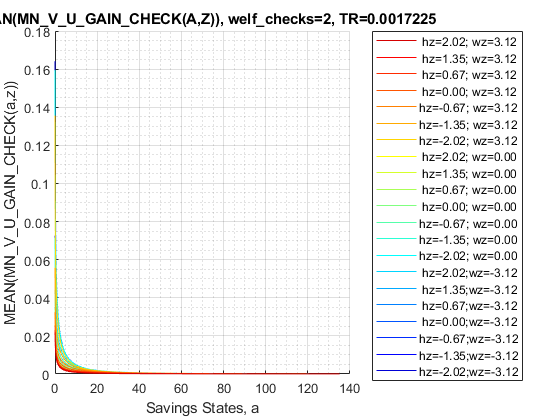

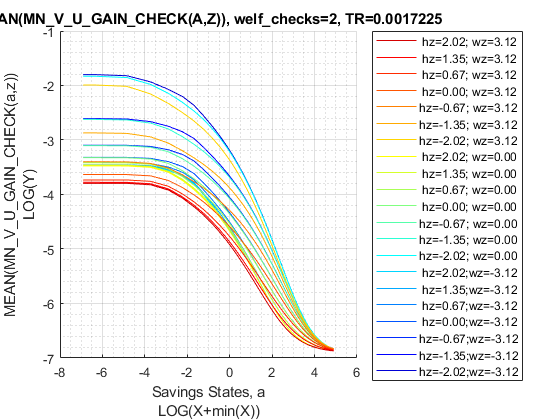

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

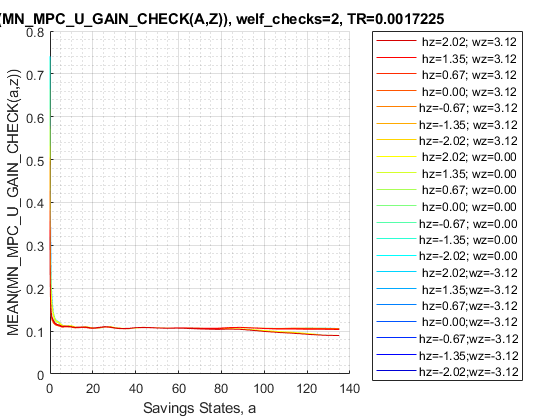

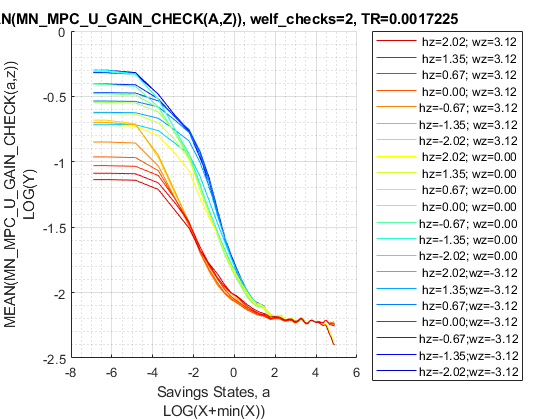

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(A,Z)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Marginal Value and MPC over Y(a,eta), Conditional On Kids, Marry, Age, Education

Income is generated by savings and shocks, what are the income levels generated by all the shock and savings points conditional on kids, marital status, age and educational levels. Plot on the Y axis MPC, and plot on the X axis income levels, use colors to first distinguish between different a levels, then use colors to distinguish between different eta levles. 

Set Up date, Select Age 37vn

, unmarried, no kids, lower education:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
% 38 year old, unmarried, no kids, lower educated
% Only Household Head Shock Matters so select up to 'n_eta_H_grid'
mn_total_inc_jemk = total_inc_VFI(19,:,1:mp_params('n_eta_H_grid'),1,1,1);
mn_V_W_gain_check_use = ev19_jaeemk_check2 - ev19_jaeemk_check0;
mn_C_W_gain_check_use = ec19_jaeemk_check2 - ec19_jaeemk_check0;

Select Age, Education, Marital, Kids Count:s

% Selections
it_age = 21; % +18
it_marital = 1; % 1 = unmarried
it_kids = 1; % 1 = kids is zero
it_educ = 1; % 1 = lower education
% Select: NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
mn_C_W_gain_check_jemk = mn_C_W_gain_check_use(it_age, :, 1:mp_params('n_eta_H_grid'), it_educ, it_marital, it_kids);
mn_V_W_gain_check_jemk = mn_V_W_gain_check_use(it_age, :, 1:mp_params('n_eta_H_grid'), it_educ, it_marital, it_kids);
% Reshape, so shock is the first dim, a is the second
mt_total_inc_jemk = permute(mn_total_inc_jemk,[3,2,1]);
mt_C_W_gain_check_jemk = permute(mn_C_W_gain_check_jemk,[3,2,1]);
mt_C_W_gain_check_jemk(mt_C_W_gain_check_jemk<=1e-10) = 1e-10;
mt_V_W_gain_check_jemk = permute(mn_V_W_gain_check_jemk,[3,2,1]);
mt_V_W_gain_check_jemk(mt_V_W_gain_check_jemk<=1e-10) = 1e-10;
% Generate meshed a and shock grid
[mt_eta_H, mt_a] = ndgrid(eta_H_grid(1:mp_params('n_eta_H_grid')), agrid);

#### Marginal Value Gains, Color as Shock, Conditional on Age, Marital, Kids, and Education

How do shocks and a impact marginal value. First plot one asset level, variation comes only from increasingly higher shocks:

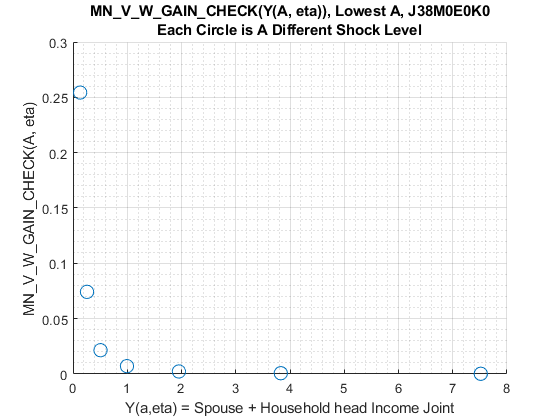

figure();
it_a = 1;
scatter((mt_total_inc_jemk(:,it_a)), (mt_V_W_gain_check_jemk(:,it_a)), 100);
title({'MN\_V\_W\_GAIN\_CHECK(Y(A, eta)), Lowest A, J38M0E0K0', ...
    'Each Circle is A Different Shock Level'});
xlabel('Y(a,eta) = Spouse + Household head Income Joint');
ylabel('MN\_V\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

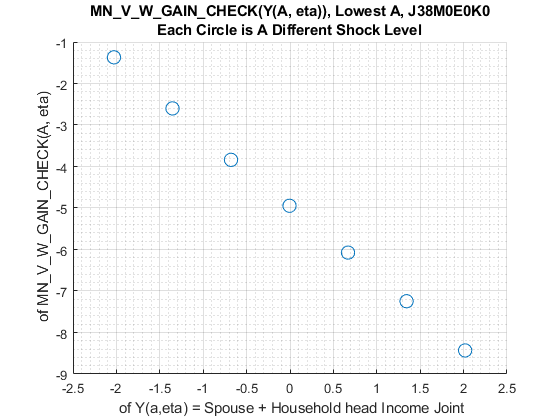

figure();
it_shock = 1;
scatter(log(mt_total_inc_jemk(:,it_a)), log(mt_V_W_gain_check_jemk(:,it_a)), 100);
title({'MN\_V\_W\_GAIN\_CHECK(Y(A, eta)), Lowest A, J38M0E0K0', ...
    'Each Circle is A Different Shock Level'});
xlabel(' of Y(a,eta) = Spouse + Household head Income Joint');
ylabel(' of MN\_V\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

Plot all asset levels:

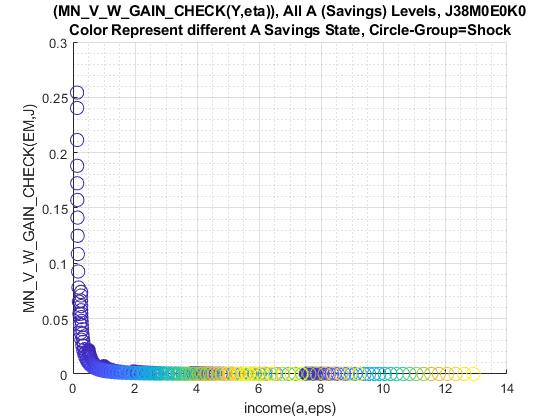

figure();
scatter((mt_total_inc_jemk(:)), (mt_V_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_V\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('MN\_V\_W\_GAIN\_CHECK(EM,J)');
grid on;
grid minor;

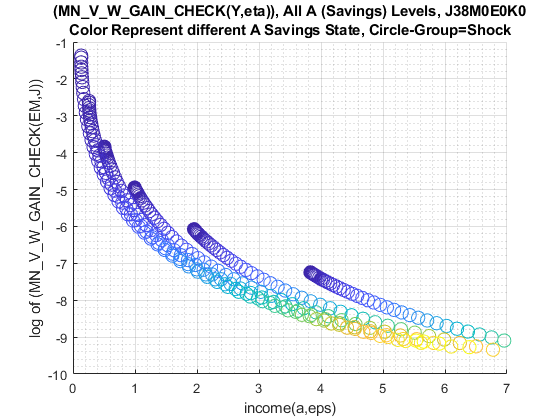

figure();
scatter((mt_total_inc_jemk(:)), log(mt_V_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_V\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('log of (MN\_V\_W\_GAIN\_CHECK(EM,J))');
xlim([0,7]);
grid on;
grid minor;

#### Marginal Consumption Gains, Color as Shock, Conditional on Age, Marital, Kids, and Education

How do shocks and a impact marginal value. First plot one asset level, variation comes only from increasingly higher shocks:

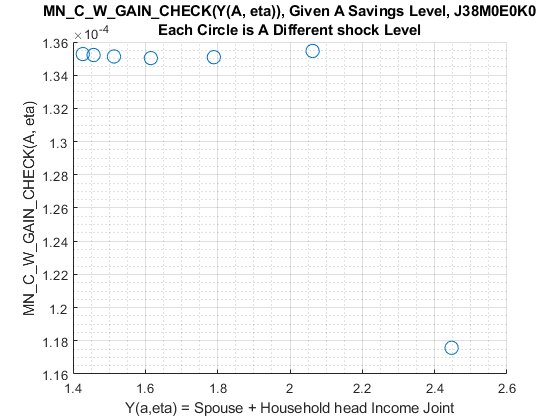

figure();
it_a = 50;
scatter(log(mt_total_inc_jemk(:,it_a)), mt_C_W_gain_check_jemk(:,it_a), 100);
title({'MN\_C\_W\_GAIN\_CHECK(Y(A, eta)), Given A Savings Level, J38M0E0K0', ...
    'Each Circle is A Different shock Level'});
xlabel('Y(a,eta) = Spouse + Household head Income Joint');
ylabel('MN\_C\_W\_GAIN\_CHECK(A, eta)');
grid on;
grid minor;

Plot all asset levels:

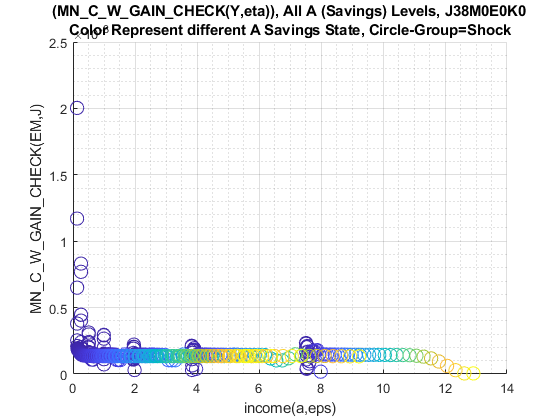

figure();
scatter((mt_total_inc_jemk(:)), (mt_C_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_C\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('income(a,eps)');
ylabel('MN\_C\_W\_GAIN\_CHECK(EM,J)');
grid on;
grid minor;

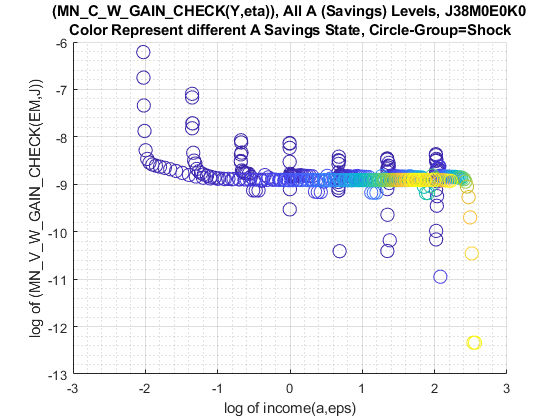

figure();
scatter(log(mt_total_inc_jemk(:)), log(mt_C_W_gain_check_jemk(:)), 100, mt_a(:));
title({'(MN\_C\_W\_GAIN\_CHECK(Y,eta)), All A (Savings) Levels, J38M0E0K0', ...
    'Color Represent different A Savings State, Circle-Group=Shock'});
xlabel('log of income(a,eps)');
ylabel('log of (MN\_V\_W\_GAIN\_CHECK(EM,J))');
grid on;
grid minor;

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption Function
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(KM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

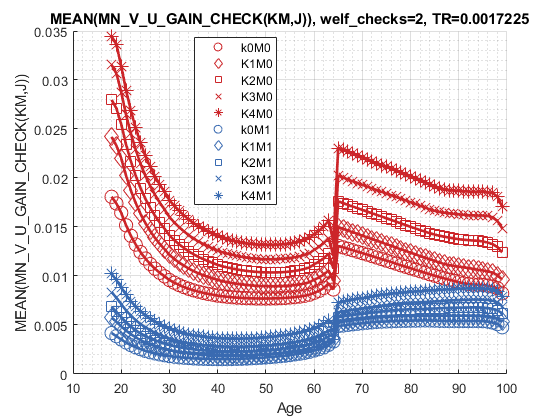

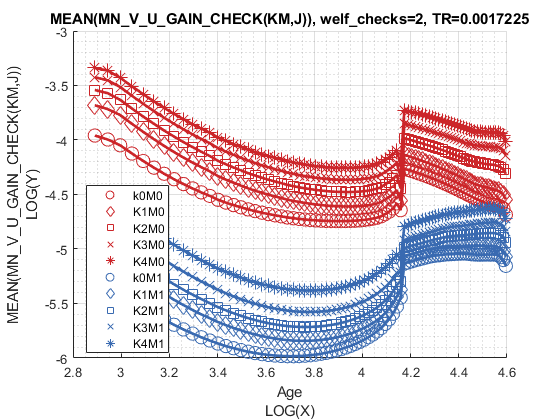

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

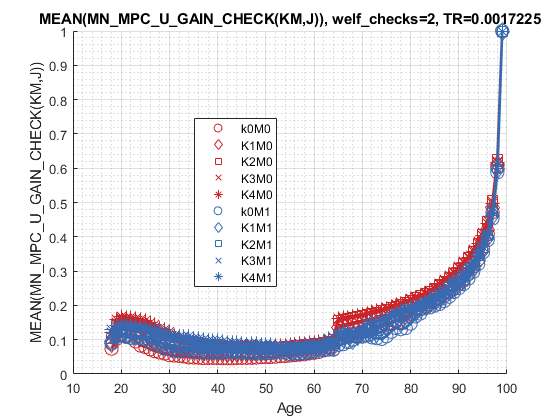

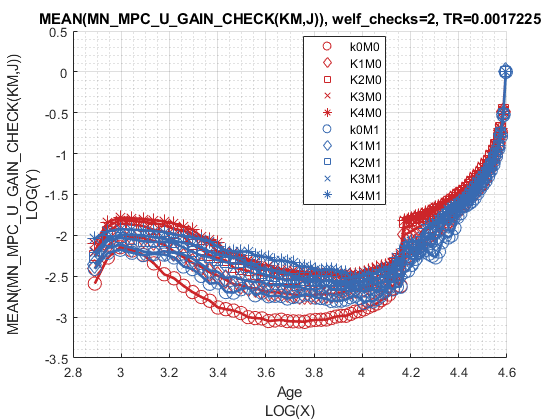

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EM,J)), MEAN(AP(EM,J)), MEAN(C(EM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
st_title = ['MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_v = ff_summ_nd_array(st_title, mn_V_U_gain_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_V_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

% Consumption
st_title = ['MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR'))];
tb_az_c = ff_summ_nd_array(st_title, mn_MPC_U_gain_share_check, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(MN_MPC_U_GAIN_CHECK(EM,J)), welf_checks=2, TR=0.0017225  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_18    mean_age_19    mean_age_20    mean_age_21    mean_age_22    mean_age_23    mean_age_24    mean_age_25    mean_age_26    mean_age_27    mean_age_28    mean_age_29    mean_age_30    mean_age_31    mean_age_32    mean_age_33    mean_age_34    mean_age_35    mean_age_36    mean_age_37    mean_age_38    mean_age_39    mean_age_40    mean_age_41    mean_age_42    mean_age_43

Graph Mean Values:

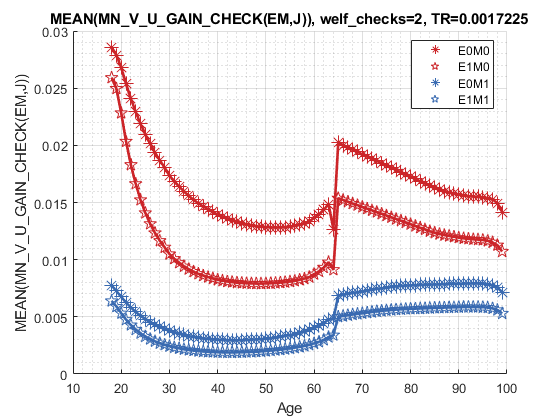

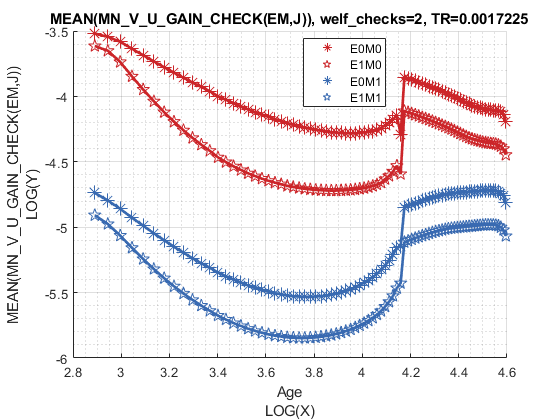

st_title = ['MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_V\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption (***MPC: Share of Check Consumed***):

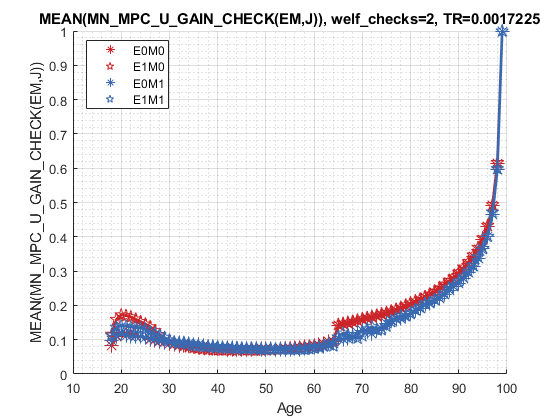

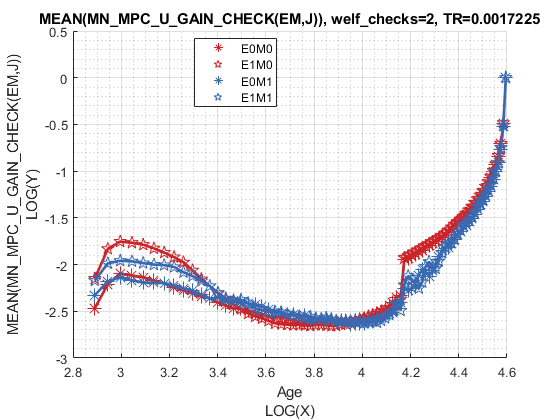

st_title = ['MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J)), welf\_checks=' num2str(welf_checks) ', TR=' num2str(mp_params('TR')) ''];
mp_support_graph('cl_st_graph_title') = {st_title};
mp_support_graph('cl_st_ytitle') = {'MEAN(MN\_MPC\_U\_GAIN\_CHECK(EM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);